1. 在 0≤t≤2Π区间内，绘制曲线y=3sint+1。  

t=0:pi/100:2*pi; %表示自变量区间
y=3*sin(t)+1  %要求函数

y =     1.0000    1.0942    1.1884    1.2823    1.3760    1.4693    1.5621    1.6544    1.7461    1.8370    1.9271    2.0162    2.1044    2.1914    2.2773    2.3620    2.4453    2.5271    2.6075    2.6863    2.7634    2.8387    2.9123    2.9839    3.0536    3.1213    3.1869    3.2503    3.3115    3.3705    3.4271    3.4812    3.5330    3.5822    3.6289    3.6730    3.7145    3.7533    3.7893    3.8226    3.8532    3.8809    3.9057    3.9278    3.9469    3.9631    3.9763    3.9867    3.9941    3.9985


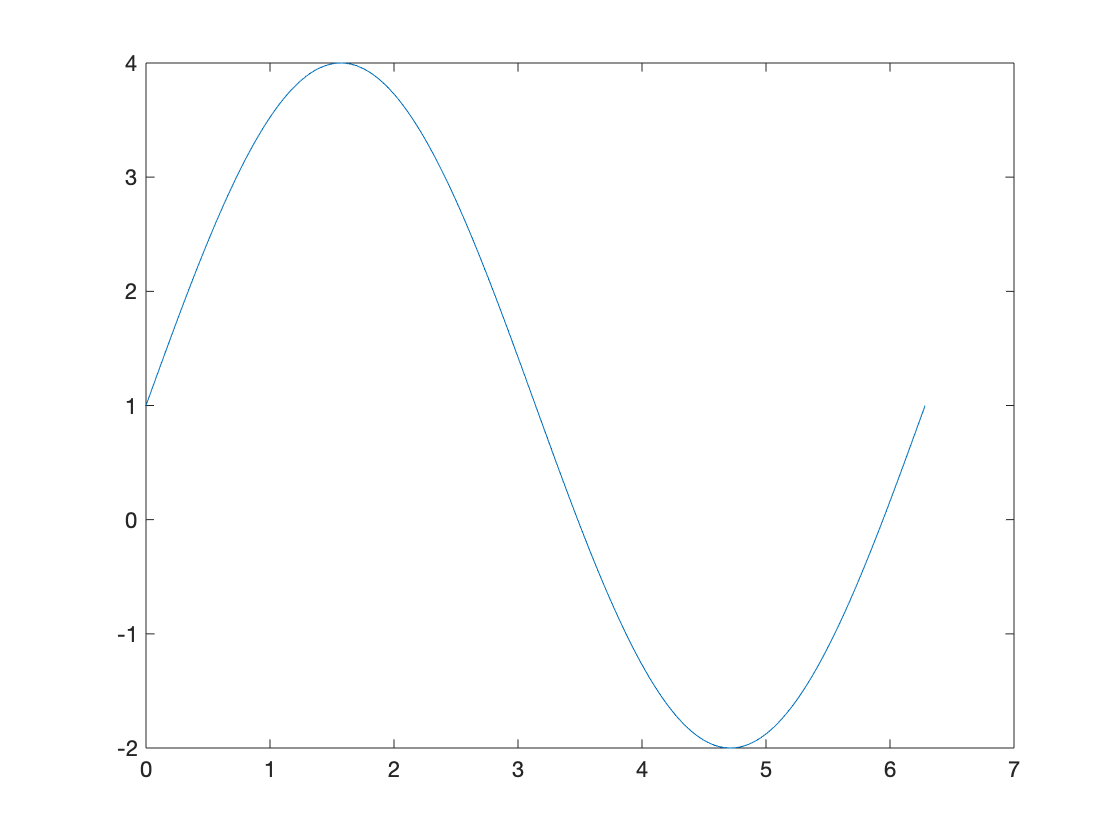

figure
plot(t,y)

2. 在同一坐标系里绘制 0≤t≤2Π区间内  正弦函数、余弦函数、正切函数和余切函数

clc;
clear;
t=0:pi/50:2*pi; %自变量取值空间

k1 = [1 26 51 76 101]  %删除正切余切函数为0时的点

k1 =      1    26    51    76   101


t(k1)=[];  %删除正切余切函数为0时的点

y1 = sin(t) %正弦函数

y1 =     0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5358    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9980    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628   -0.0628   -0.1253


%plot(y1)
y2 = cos(t) %余弦函数

y2 =     0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628   -0.0628   -0.1253   -0.1874   -0.2487   -0.3090   -0.3681   -0.4258   -0.4818   -0.5358   -0.5878   -0.6374   -0.6845   -0.7290   -0.7705   -0.8090   -0.8443   -0.8763   -0.9048   -0.9298   -0.9511   -0.9686   -0.9823   -0.9921   -0.9980   -0.9980   -0.9921


%plot(y2)
y3 = tan(t) %正切函数

y3 =     0.0629    0.1263    0.1908    0.2568    0.3249    0.3959    0.4706    0.5498    0.6346    0.7265    0.8273    0.9391    1.0649    1.2088    1.3764    1.5757    1.8190    2.1251    2.5257    3.0777    3.8947    5.2422    7.9158   15.8945  -15.8945   -7.9158   -5.2422   -3.8947   -3.0777   -2.5257   -2.1251   -1.8190   -1.5757   -1.3764   -1.2088   -1.0649   -0.9391   -0.8273   -0.7265   -0.6346   -0.5498   -0.4706   -0.3959   -0.3249   -0.2568   -0.1908   -0.1263   -0.0629    0.0629    0.1263


%plot(y3)
y4 = cot(t) %余切函数

y4 =    15.8945    7.9158    5.2422    3.8947    3.0777    2.5257    2.1251    1.8190    1.5757    1.3764    1.2088    1.0649    0.9391    0.8273    0.7265    0.6346    0.5498    0.4706    0.3959    0.3249    0.2568    0.1908    0.1263    0.0629   -0.0629   -0.1263   -0.1908   -0.2568   -0.3249   -0.3959   -0.4706   -0.5498   -0.6346   -0.7265   -0.8273   -0.9391   -1.0649   -1.2088   -1.3764   -1.5757   -1.8190   -2.1251   -2.5257   -3.0777   -3.8947   -5.2422   -7.9158  -15.8945   15.8945    7.9158


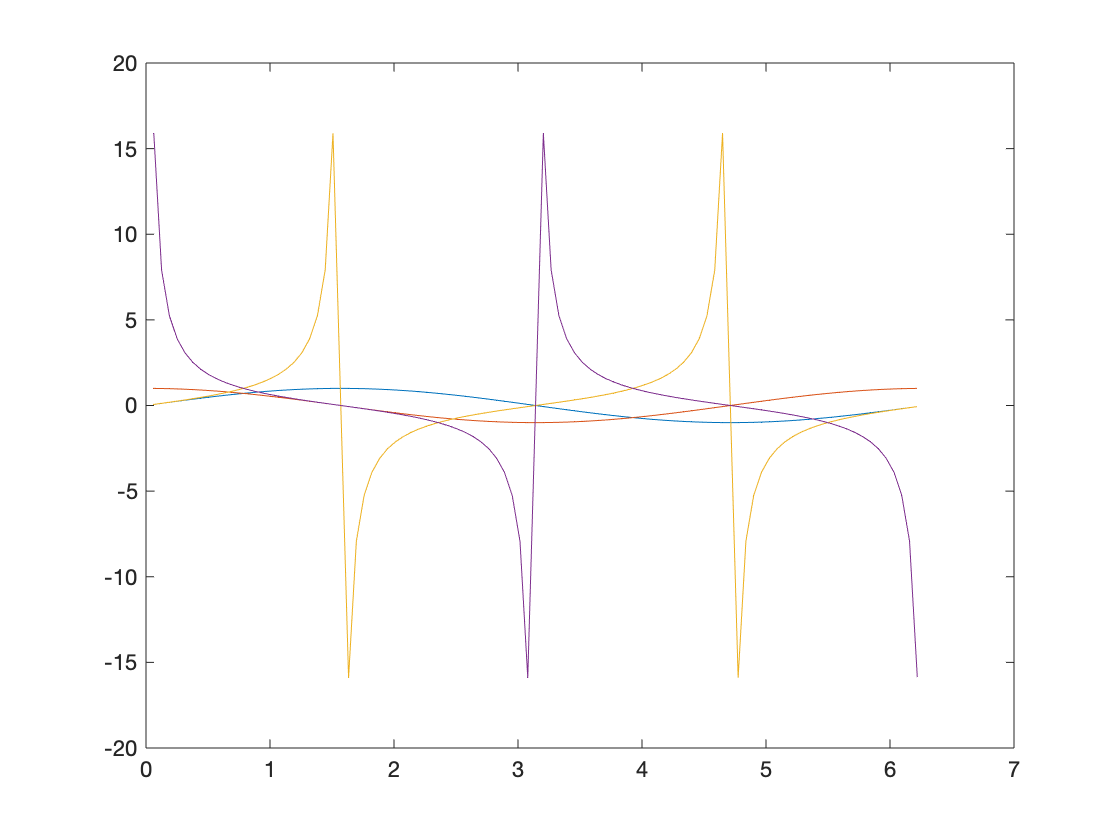

%plot(y4)
%绘图
figure
plot(t,y1,t,y2,t,y3,t,y4)

%plot(y1,y2,y3,y4)

3. 利用polar()函数绘制轮胎图和笛卡尔心形图。  

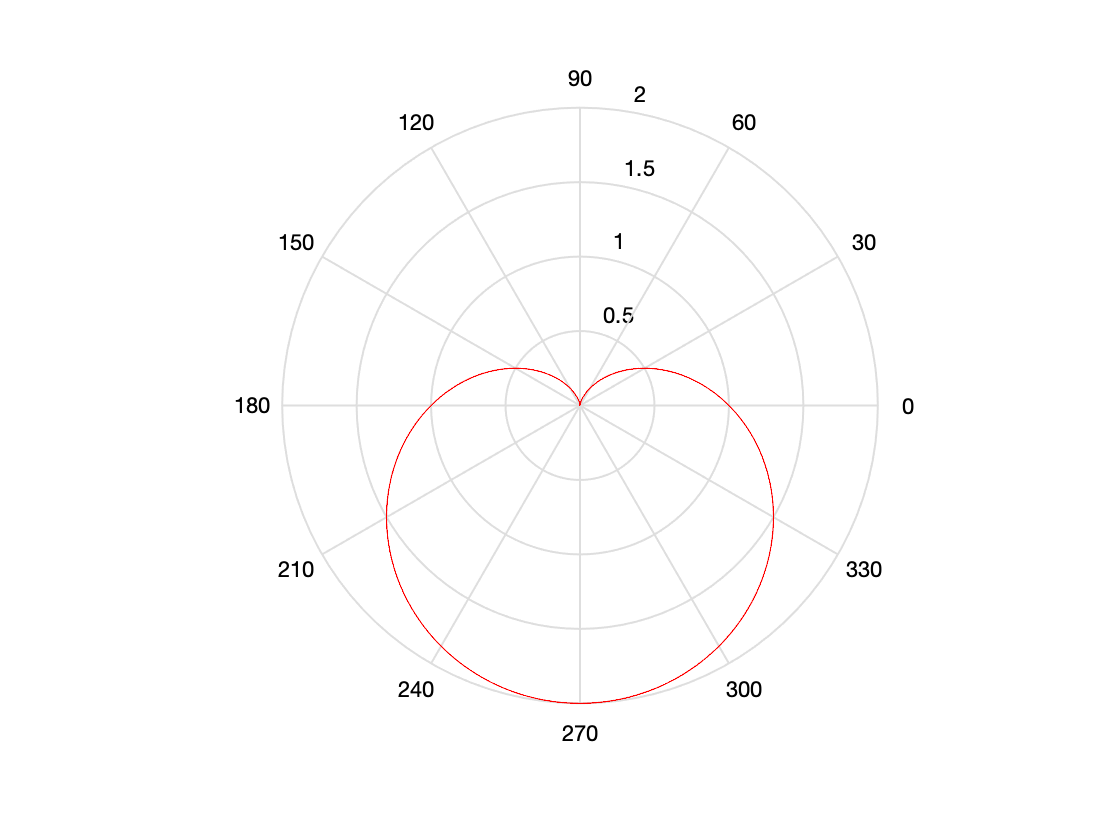

theta=-pi:0.001:pi; %角度取值范围
%绘制心型图
r=1-sin(theta);
%r=1+cos(theta)
polar(theta,r,'r');

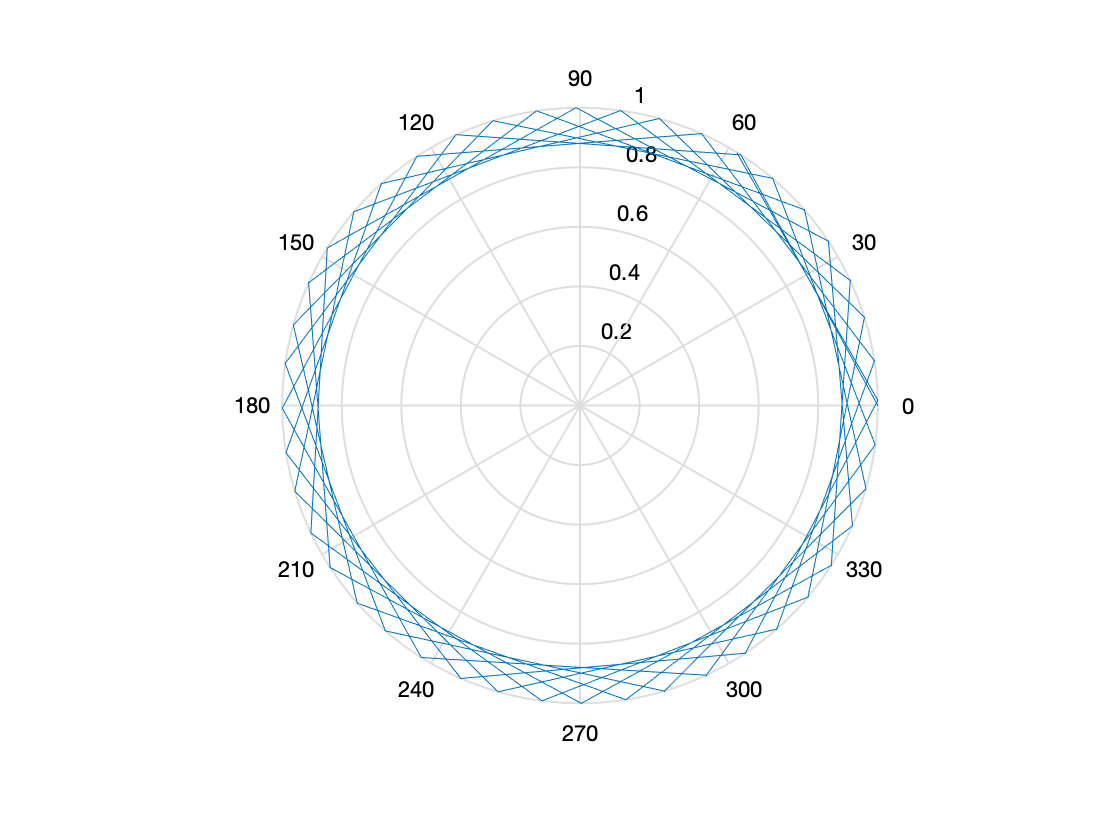

%绘制轮胎图
theta=0:45; %设定角度
rho=ones(1,length(theta)); %设定对应角度的半径
%绘图
figure
polar(theta,rho)

4. 用不同标度在同一坐标内绘制曲线y1=0.2e-0.5xcos（4Πx）和y2=2e-0.5xcos(Πx)

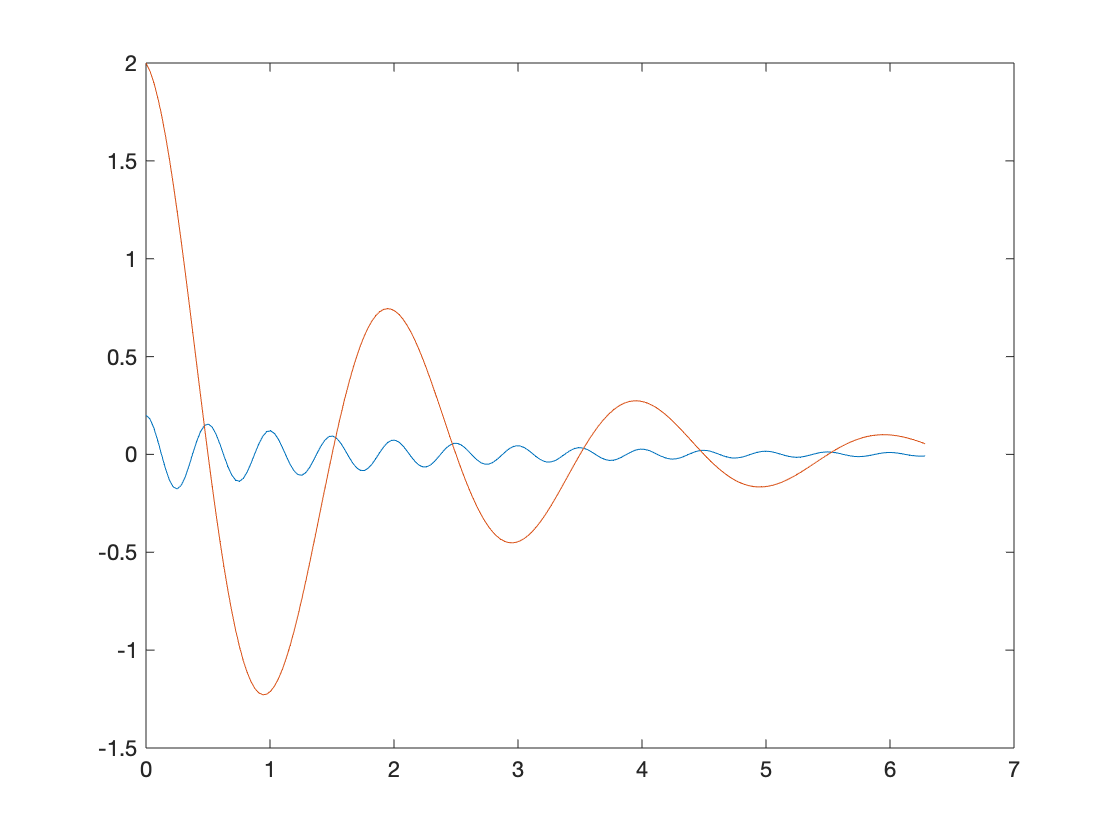

x=0:pi/100:2*pi; % 生成曲线
y1=0.2*exp(-0.5*x).*cos(4*pi*x);
y2=2*exp(-0.5*x).*cos(pi*x);
% 绘图
figure
plot(x,y1,x,y2);

5. 绘制peak()函数的等高线。  

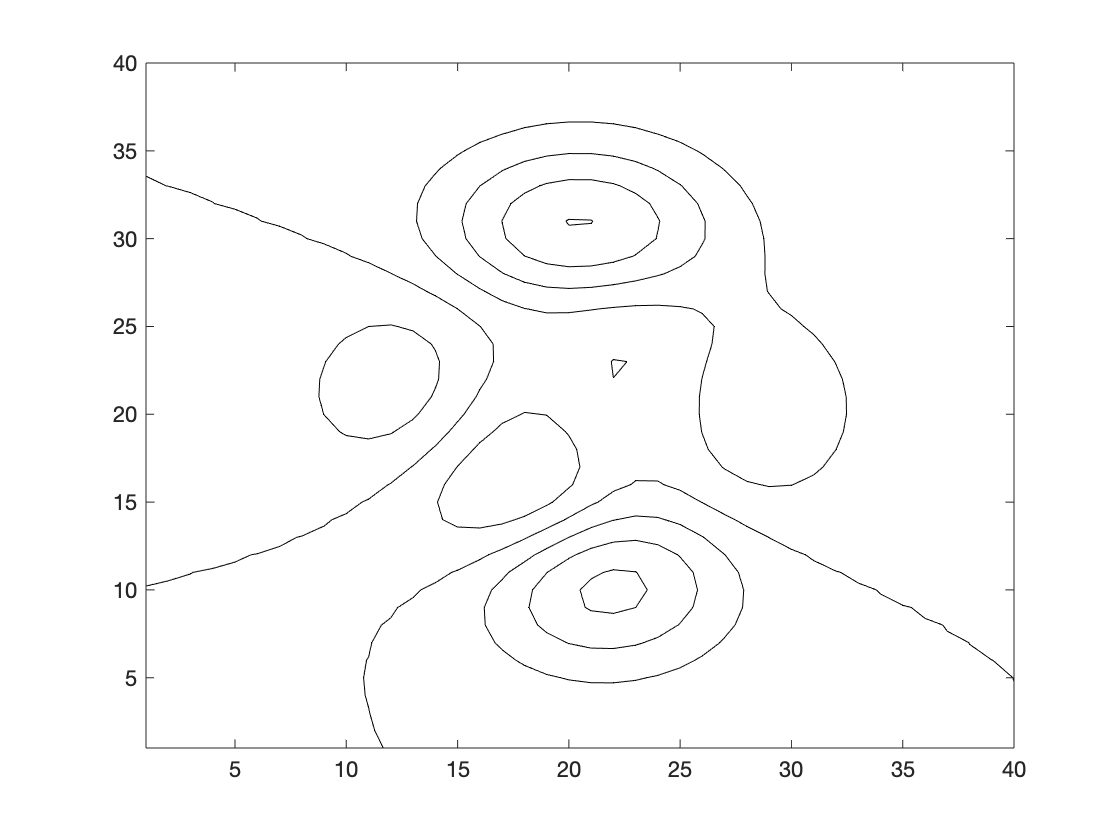

z = peaks(40); %调用peaks函数
figure
contour(z,'k') % contour(Z)- 矩阵的等高线图

6. 在同一坐标内，分别用不同线型和颜色绘制曲线  y1=0.2e-0.5xcos(4Πx)和y2=2e-0.5xcos((Πx)

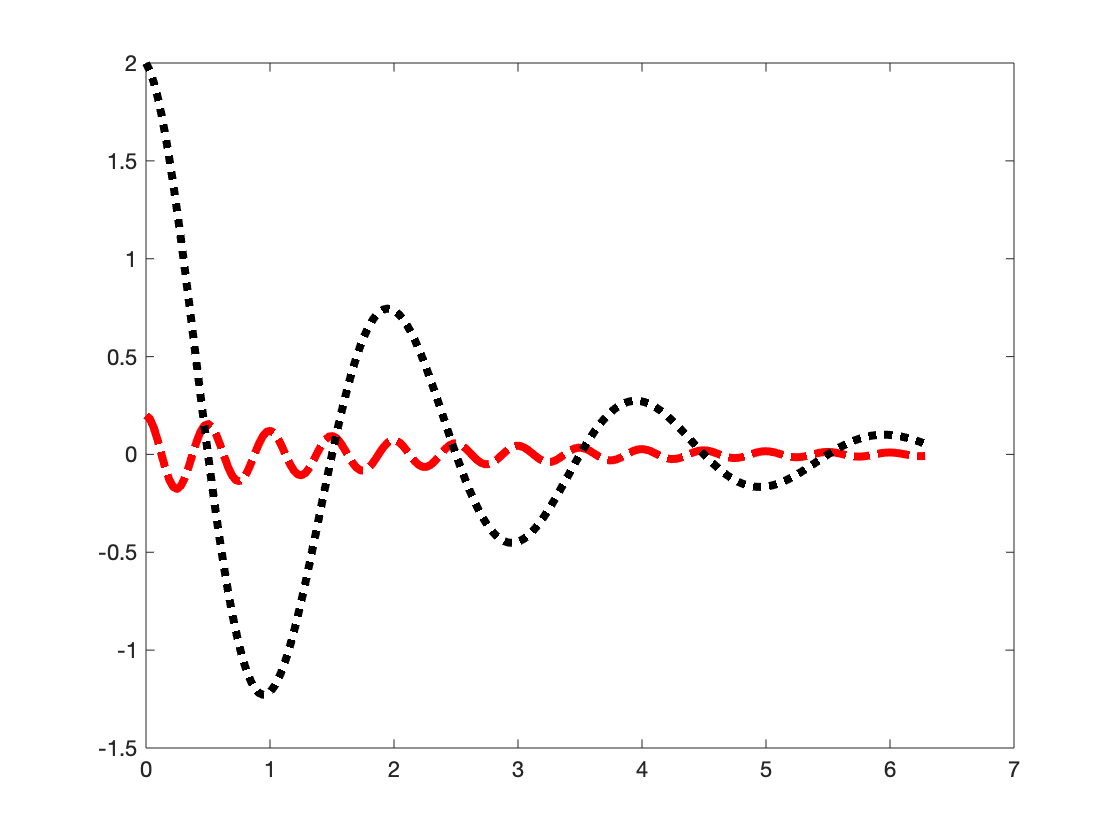

x=0:pi/100:2*pi; % 生成曲线
y1=0.2*exp(-0.5*x).*cos(4*pi*x);
y2=2*exp(-0.5*x).*cos(pi*x);
% 绘图
figure
plot(x, y1, 'r-.', x, y2, 'k:', 'LineWidth',4);

7. 绘制正弦曲线，设置图形的标题为y=sin(x),设置x轴的标注为x， y轴的标注为sin(x), 并对曲线进行文本标注。  

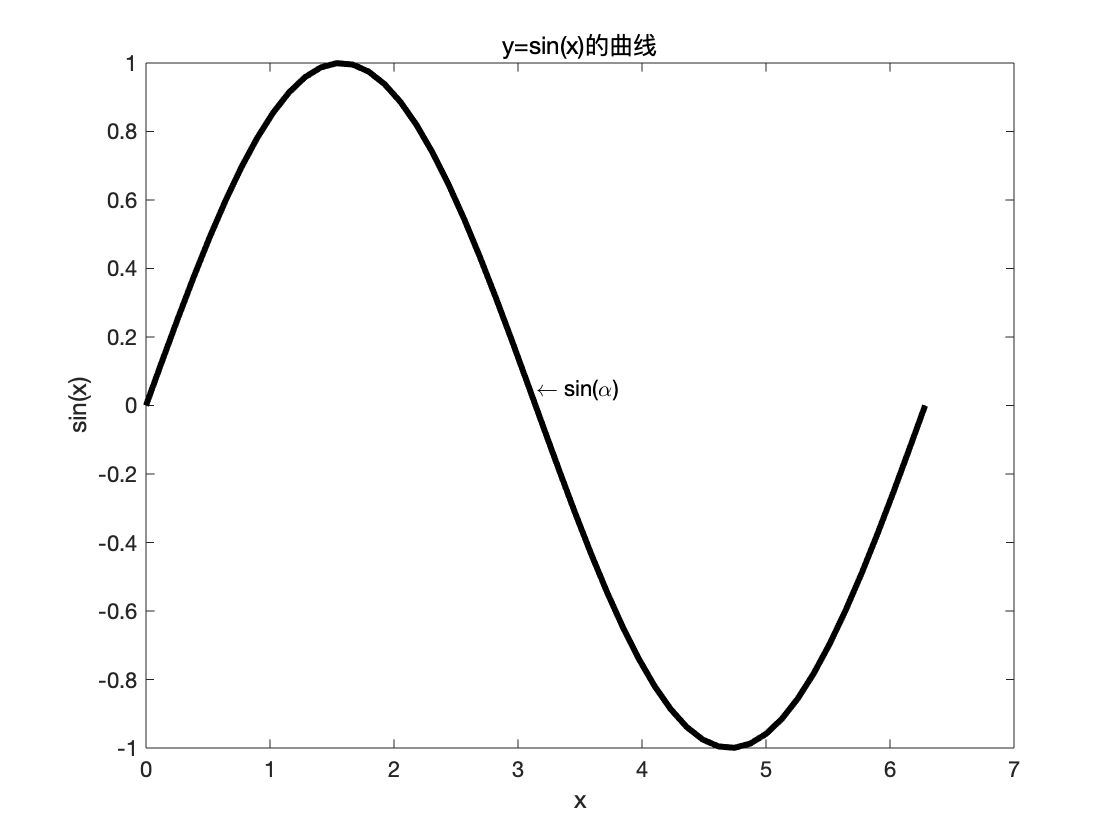

x = linspace(0, 2*pi, 50); % 横坐标轴
y = sin(x); % 生成数据点，纵坐标轴
%plot(x,y)

% 绘图
figure
plot(x, y, 'k-', 'LineWidth', 3) % 设置线宽为3
title('y=sin(x)的曲线') % 设置标题
xlabel('x') % 设置x轴的标注
ylabel('sin(x)') % 设置y轴的标注
% 文本标注
text(pi, 0.05, '\leftarrow sin(\alpha)')

8. 绘制抛物线和三次幂曲线，设置图形的标题、 x轴和y轴的标注、设置曲线文本标准、设置图例标注。 

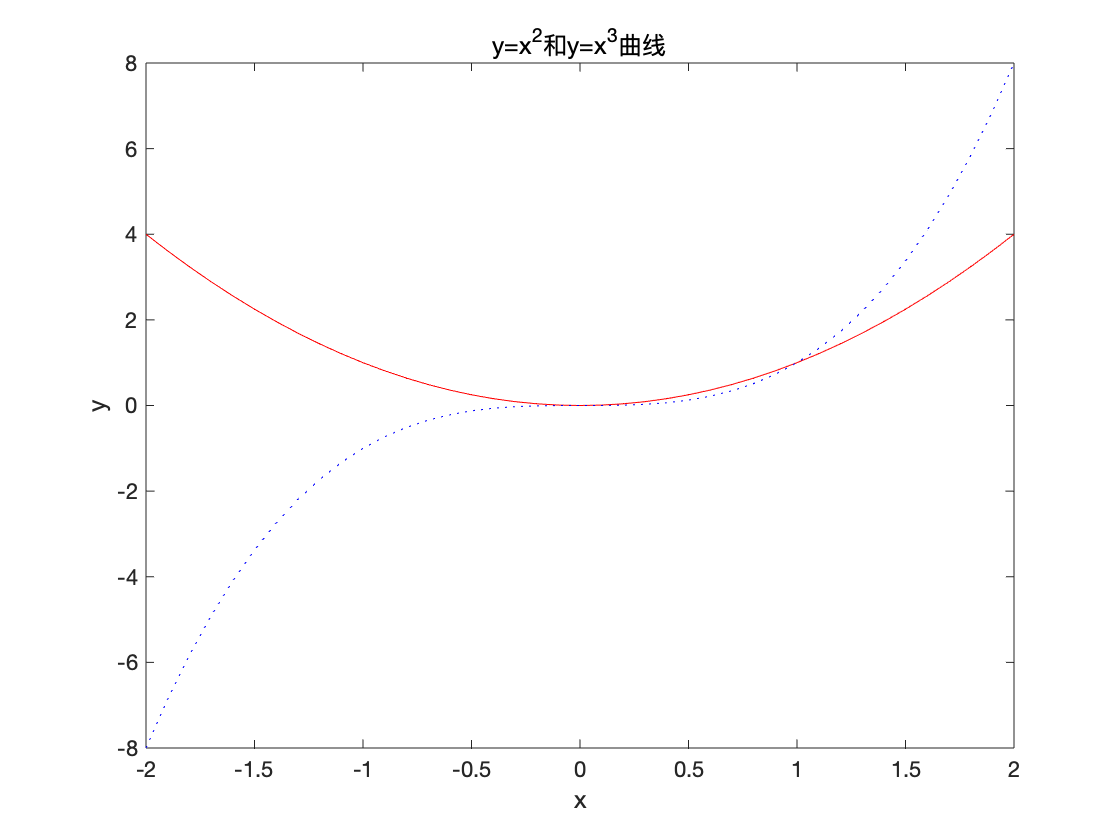

x = -2:.1:2; % 横轴
y1 = x.^2;y2 = x.^3; % 曲线数据
% 绘图
figure
plot(x,y1, 'r-', x, y2, 'b:')
title('y=x^2和y=x^3曲线') % 标题标注
% 坐标轴标注
xlabel('x')
ylabel('y')

% 文本标注
gtext('y = x^2', 'FontName', 'Times New Roman','FontSize', 16)

错误使用 plotedit (line 123)
通过 uifigure 函数创建的图窗不支持该功能。有关详细信息，请参阅 App 设计工具中的图形支持。

出错 uisuspend (line 48)
            'ploteditEnable',        plotedit(fig,'getenabletools'), ...        

出错 

gtext('y = x^3', 'FontName', 'Times New Roman','FontSize', 16)
% 图例标注
legend('y=x^2', 'y=x^3')

9. 绘制两条随机误差曲线，同时绘制出利用axis()函数修改成相同比例后的误差曲线。

y1 = 0.1*rand(5)

y1 =     0.0531    0.0469    0.0311    0.0654    0.0229
    0.0779    0.0012    0.0529    0.0689    0.0913
    0.0934    0.0337    0.0166    0.0748    0.0152
    0.0130    0.0162    0.0602    0.0451    0.0826
    0.0569    0.0794    0.0263    0.0084    0.0538


y2 = rand(5) %生成两条随机误差曲线

y2 =     0.9961    0.0046    0.3998    0.1818    0.5797
    0.0782    0.7749    0.2599    0.2638    0.5499
    0.4427    0.8173    0.8001    0.1455    0.1450
    0.1067    0.8687    0.4314    0.1361    0.8530
    0.9619    0.0844    0.9106    0.8693    0.6221


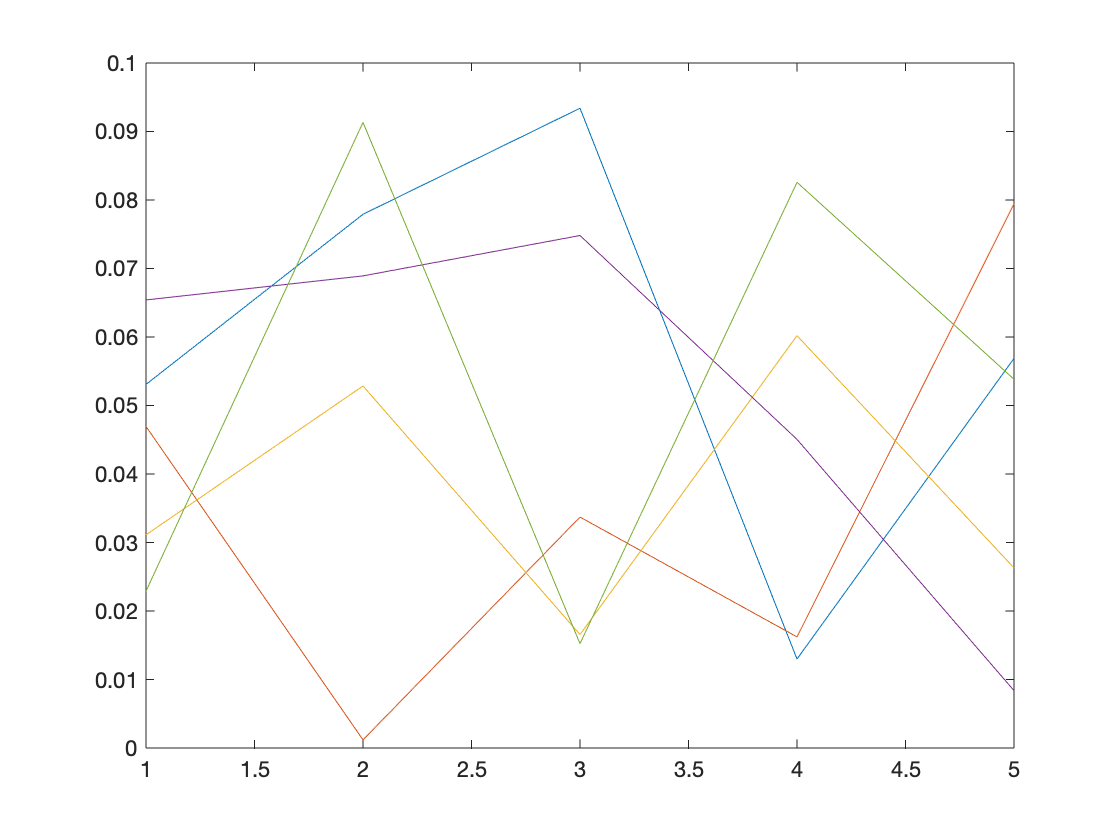

figure
plot(y1)

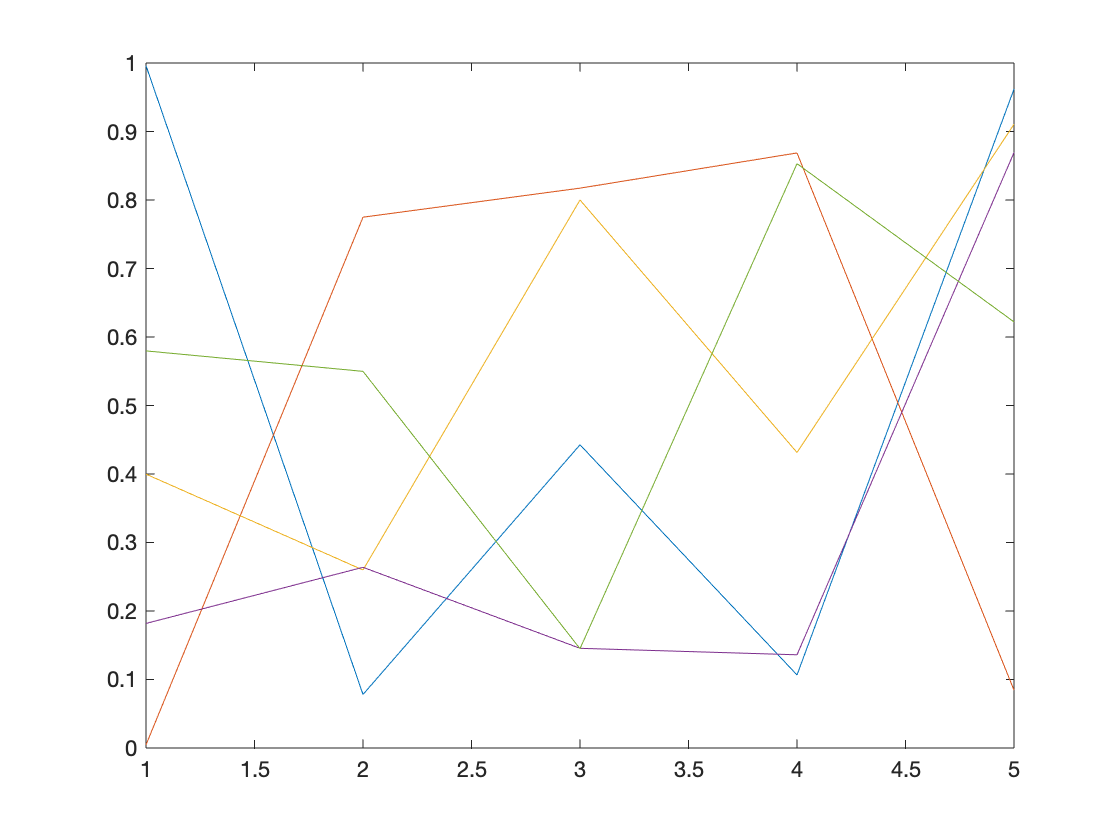

plot(y2)

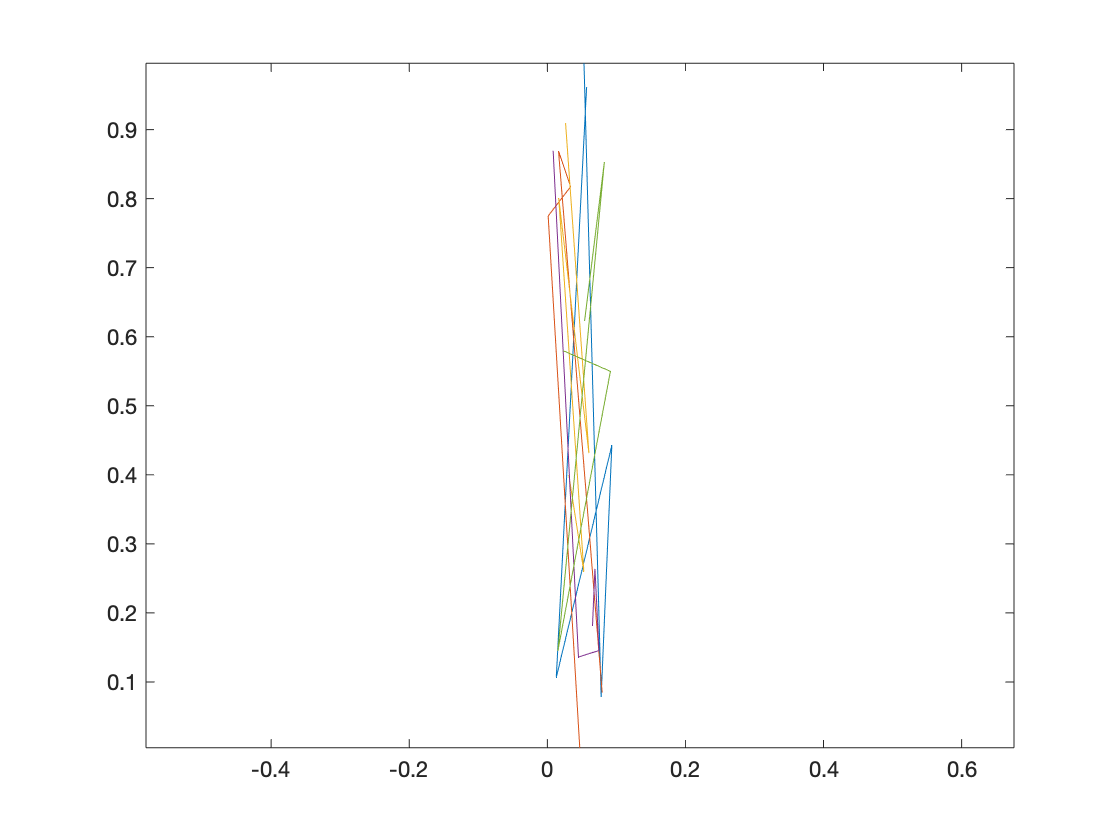


plot(y1,y2)
axis equal %相同比例

10. 绘制函数 y=e^x 的半对数坐标图形，并绘制函数 y=e^x的对数坐标图形。

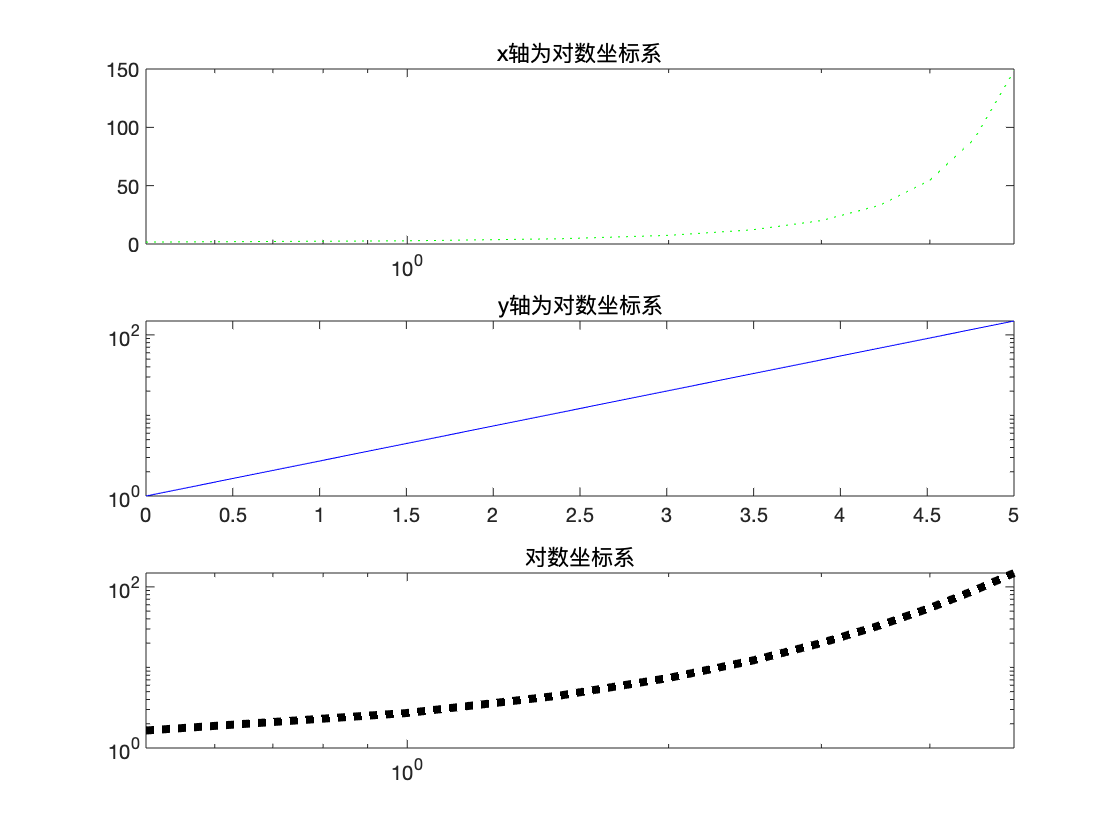

% x轴
x=0:0.5:5;
% y轴
y = exp(x);
% 绘图
figure

% 半对数坐标系
subplot(3, 1, 1)
semilogx(x, y, 'g:')
title('x轴为对数坐标系')
subplot(3, 1, 2)
semilogy(x, y, 'b-')
title('y轴为对数坐标系')
% 对数坐标系
subplot(3, 1, 3)
loglog(x, y, 'k:', 'LineWidth',4)
title('对数坐标系')

  11. 有一位研究生，在一年中平均每月的费用为生活费590元，资料费130元，电话费45元，购买衣服200元，其他费用55元。请以**饼图**表示出他每月的消费比例，并在饼图中分离出使用最多的费用和使用最少的费用的切片。  

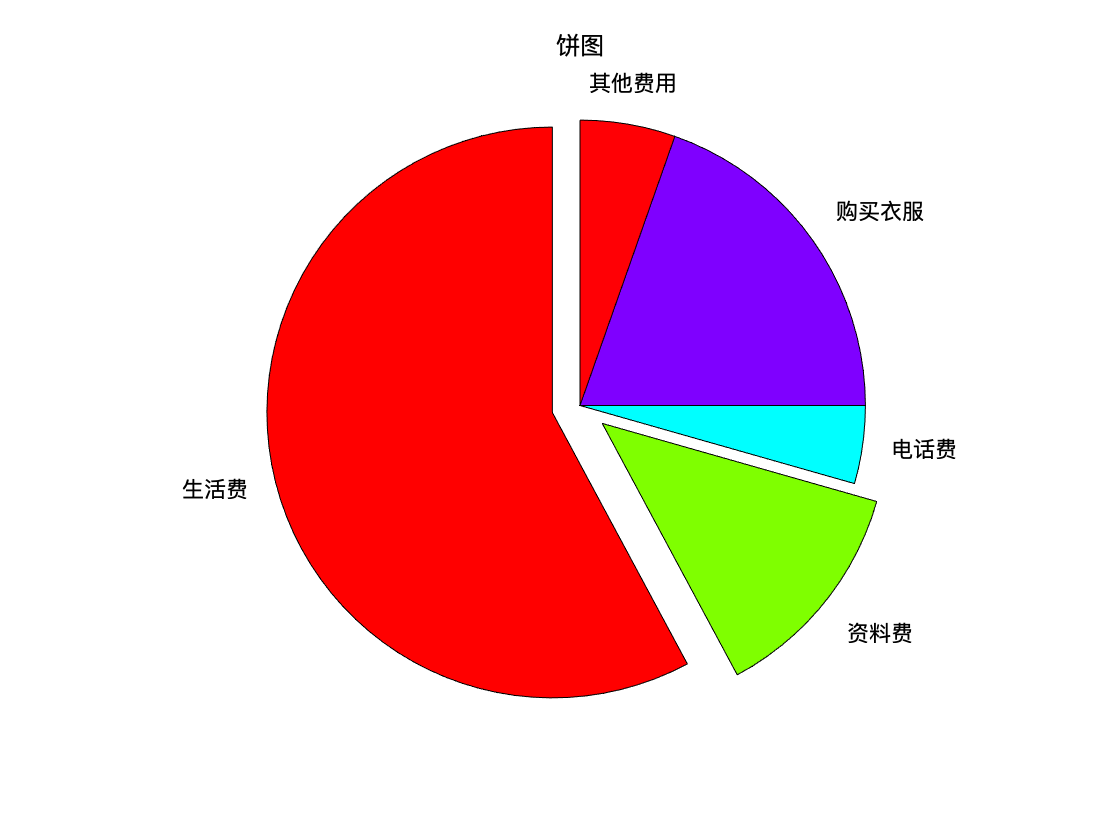

% 数据准备
x=[590 130 45 200 55];
% 分离显示设置
explode=[1 1 0 0 0];
% 绘图
figure()
colormap hsv
pie(x,explode,{'生活费','资料费','电话费','购买衣服','其他费用'})
title('饼图')

12. 有一位研究生，在一年中平均每月的费用为生活费590元，资料费130元，电话费45元，购买衣服200元，其他费用55元。请以**柱状图**表示他每月的消费比例。  

% 数据准备
y=[590 130 45 200 55];
x=1:5

x =      1     2     3     4     5


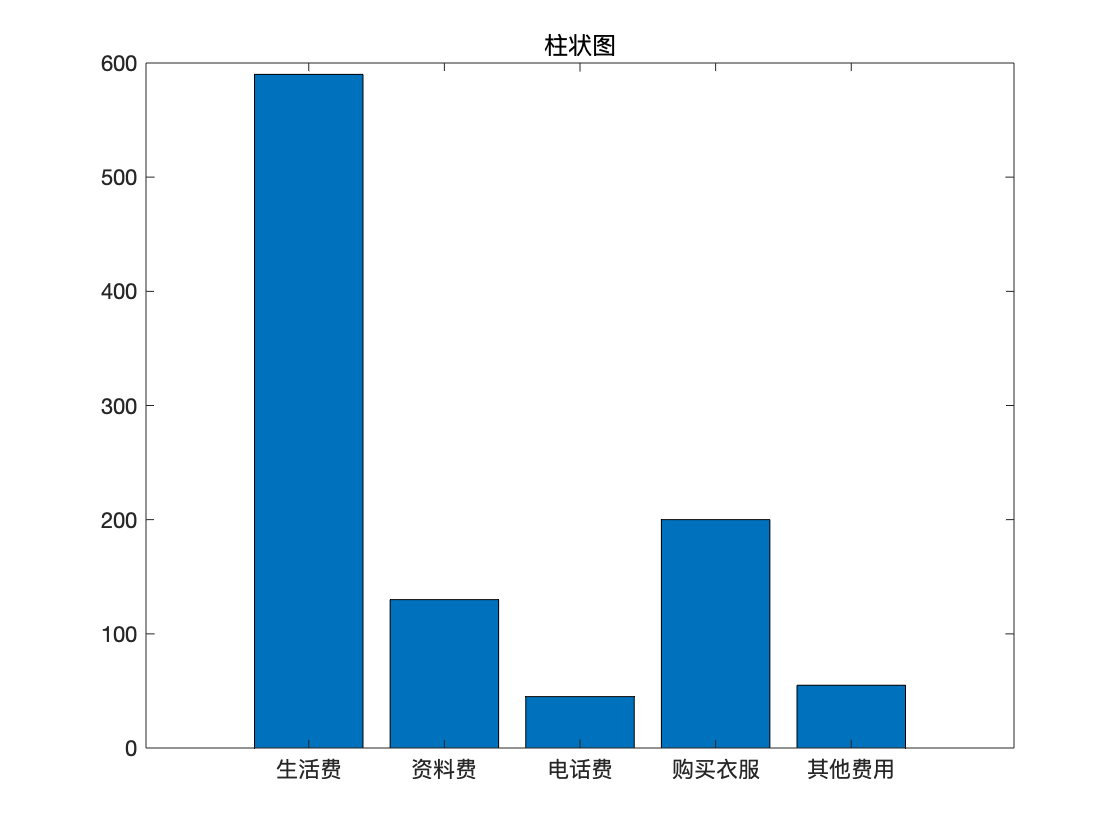

% 绘图
figure
bar(x,y)
title('柱状图');
set(gca,'xTicklabel',{'生活费','资料费','电话费','购买衣服','其他费用'})

13. 绘制peak()函数的三维等高线图和三维表面图。 

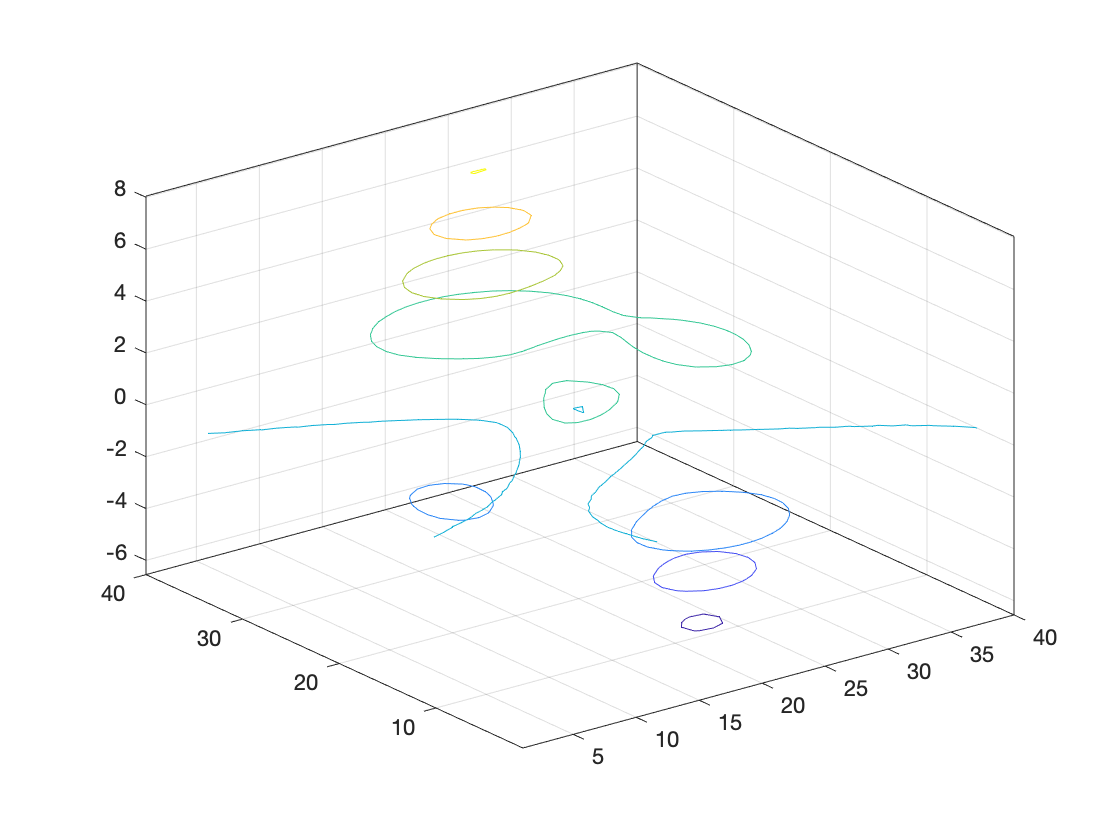

z = peaks(40); %调用peaks函数
figure
contour3(z) %绘制三维等高线

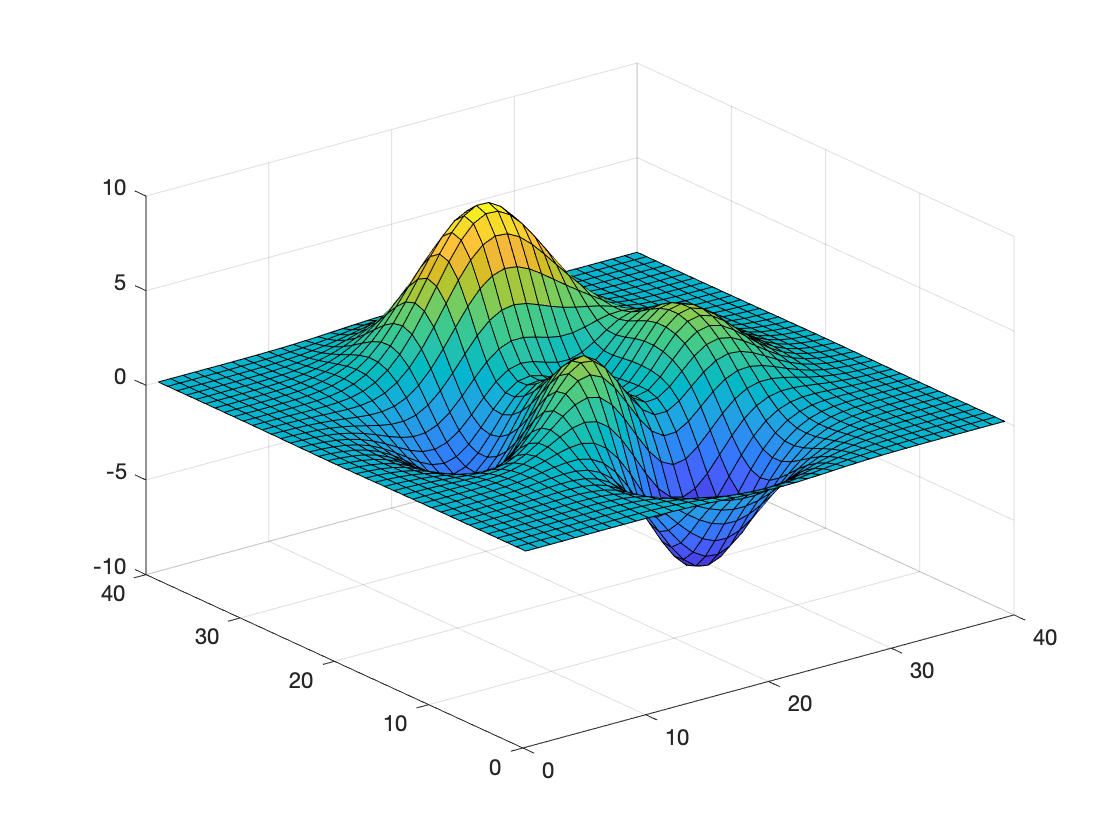

surf(z) %绘制三维表面图

 14. 绘制简单的柱面图和球形图。  

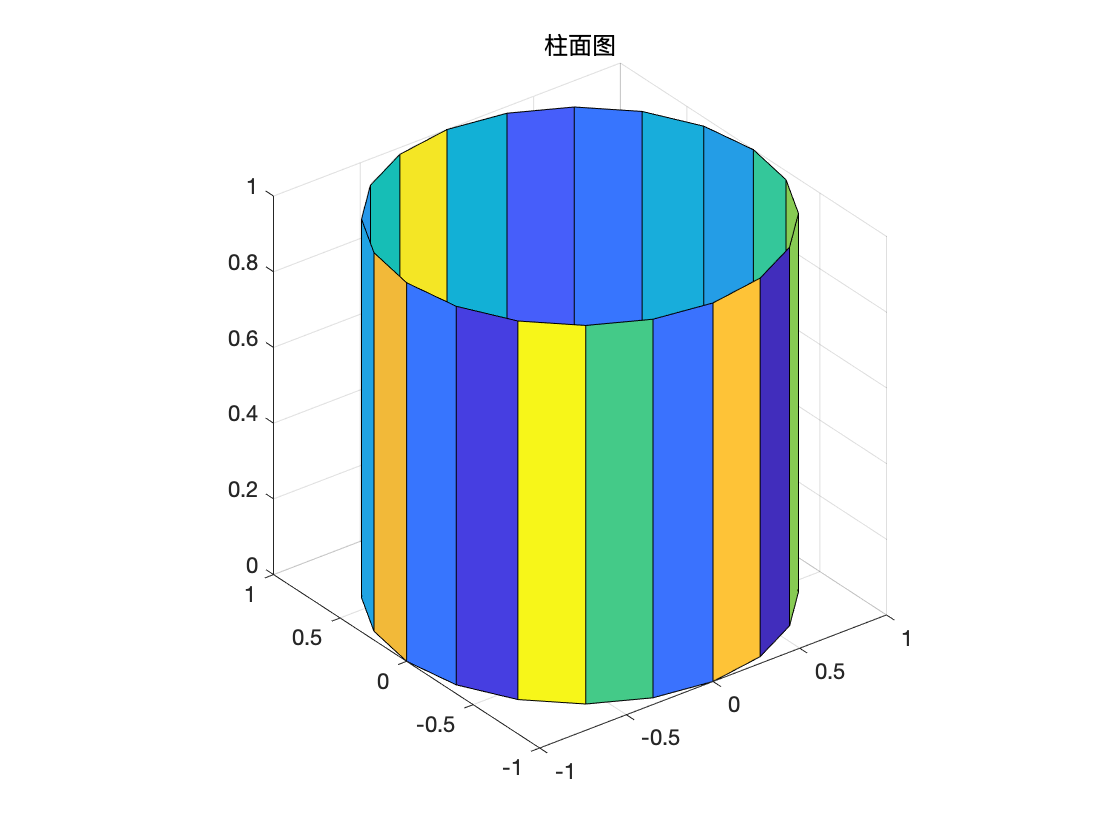

%绘制柱面图
cylinder
axis square
h = findobj('Type','surface');
set(h,'CData',rand(size(get(h,'CData'))))
title('柱面图')

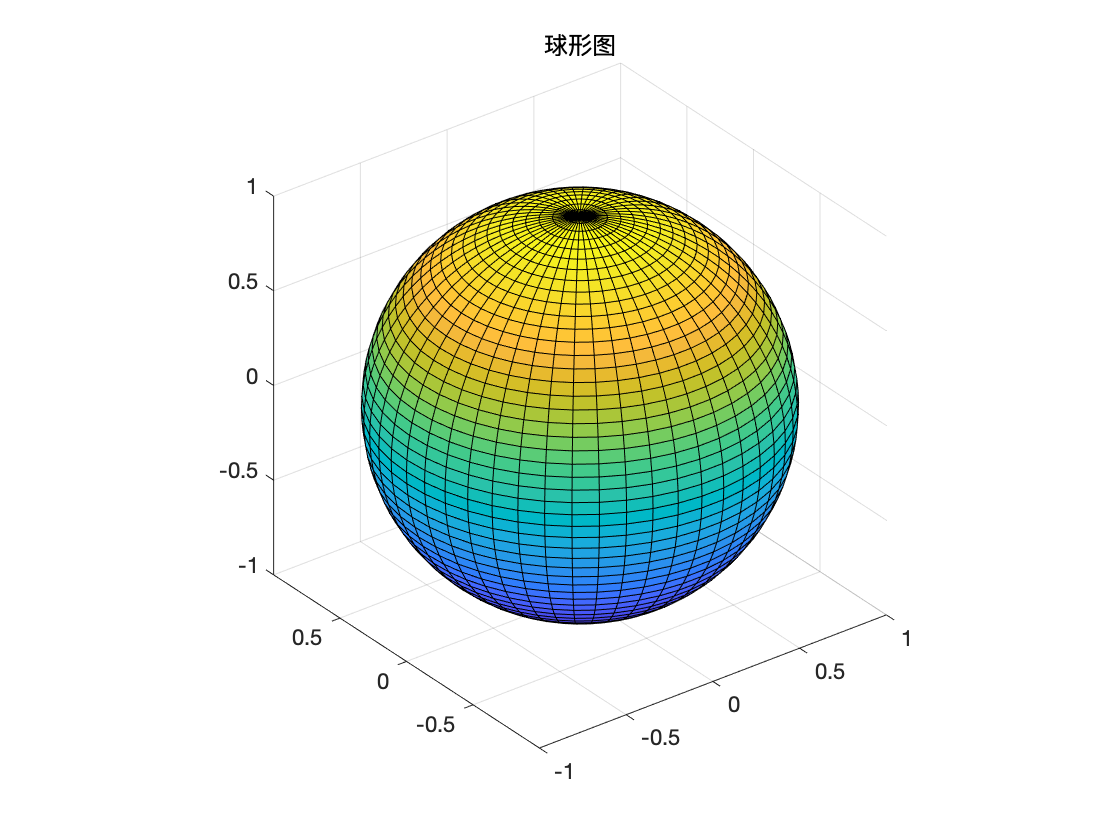

%绘制球面图
sphere(50)
axis equal
title('球形图')